# Exam 2024 dec

clear all
clc


# Problem 1

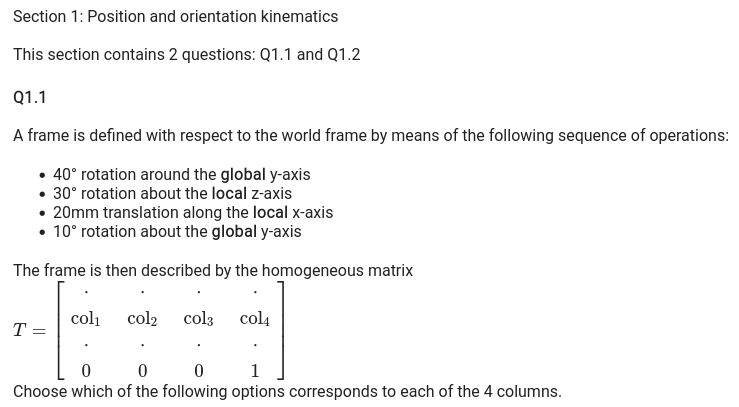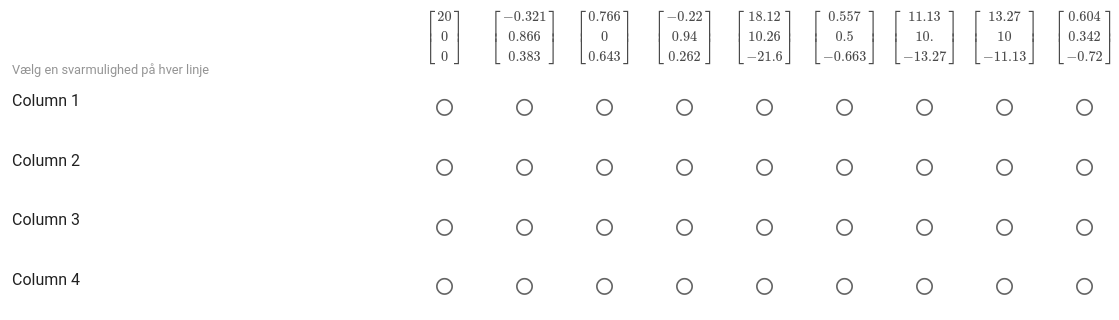

syms theta1 theta2 theta3
Rx = [1 0 0; 0 cos(theta1) -sin(theta1); 0 sin(theta1) cos(theta1)];
Ry = [cos(theta2) 0 sin(theta2); 0 1 0; -sin(theta2) 0 cos(theta2)];
Rz = [cos(theta3) -sin(theta3) 0; sin(theta3) cos(theta3) 0; 0 0 1];

gRy1 = subs(Ry,theta2,deg2rad(40));
lRz = subs(Rz,theta3,deg2rad(30));

gRy2 = subs(Ry,theta2,deg2rad(10));

T = eval(lRz+gRy1+gRy2)

T =     2.6169   -0.5000    0.8164
    0.5000    2.8660         0
   -0.8164         0    2.7509


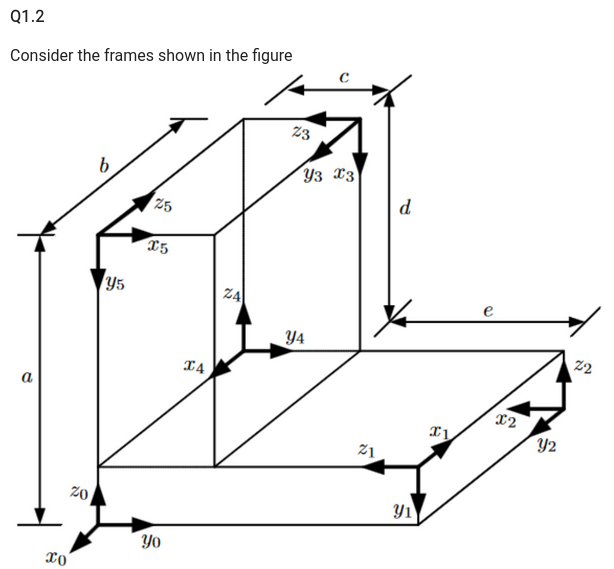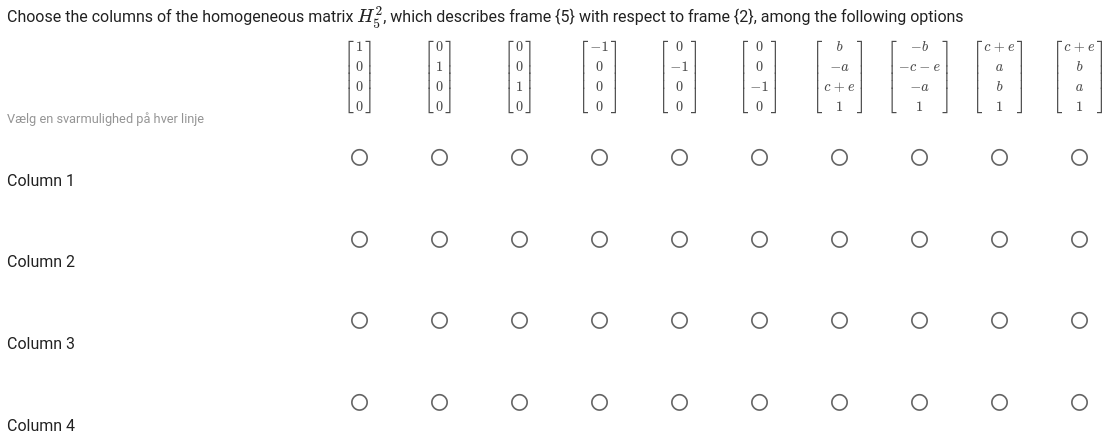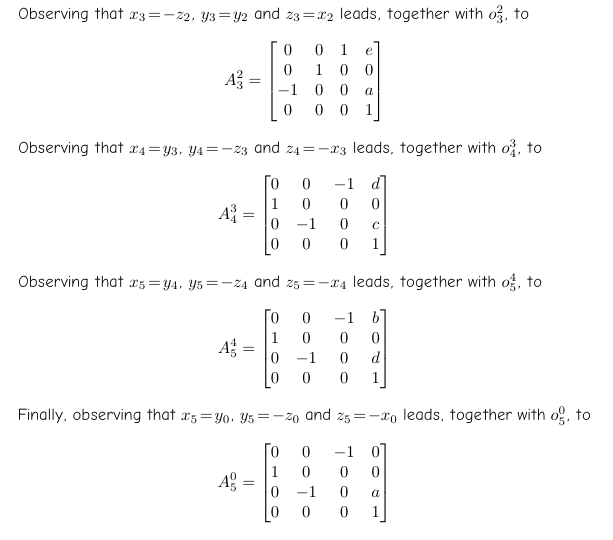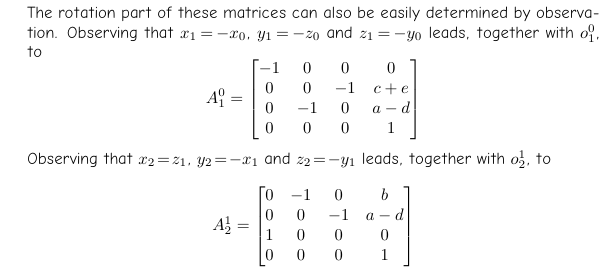

syms e d b a c
A01 = [-1 0 0 0; 0 0 -1 c+e; 0 -1 0 a-d; 0 0 0 1];
A12 = [0 -1 0 b; 0 0 -1 a-d; 1 0 0 0; 0 0 0 1];
A23 = [0 0 1 e; 0 1 0 0; -1 0 0 a; 0 0 0 1];
A34 = [0 0 -1 d; 1 0 0 0; 0 -1 0 e; 0 0 0 1];
A45 = [0 0 -1 b; 1 0 0 0; 0 -1 0 d; 0 0 0 1];
A05 = [0 0 -1 0; 1 0 0 0; 0 -1 0 a; 0 0 0 1];
A05-(A01+A12)

$$ans = \left(\begin{array}{cccc} 1 & 1 & -1 & -b\\ 1 & 0 & 2 & d-c-a-e\\ -1 & 0 & 0 & d\\ 0 & 0 & 0 & -1 \end{array}\right)$$

A23+A34+A45

$$ans = \left(\begin{array}{cccc} 0 & 0 & -1 & b+d+e\\ 2 & 1 & 0 & 0\\ -1 & -2 & 0 & a+d+e\\ 0 & 0 & 0 & 3 \end{array}\right)$$

# Problem 2

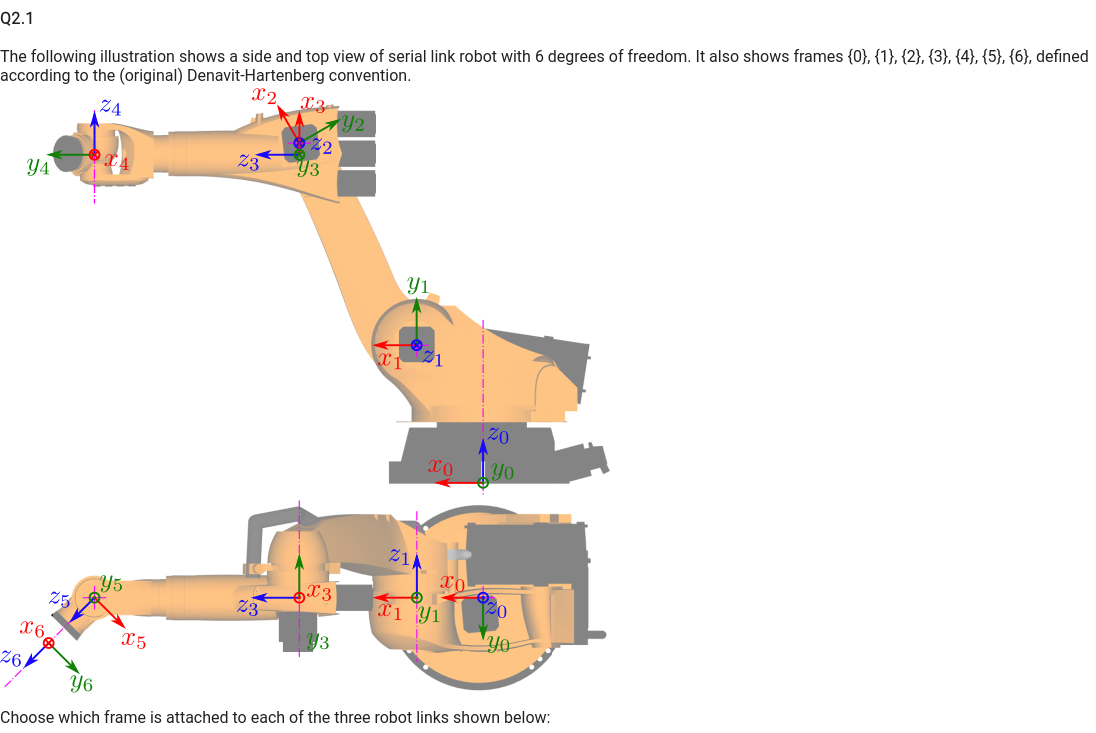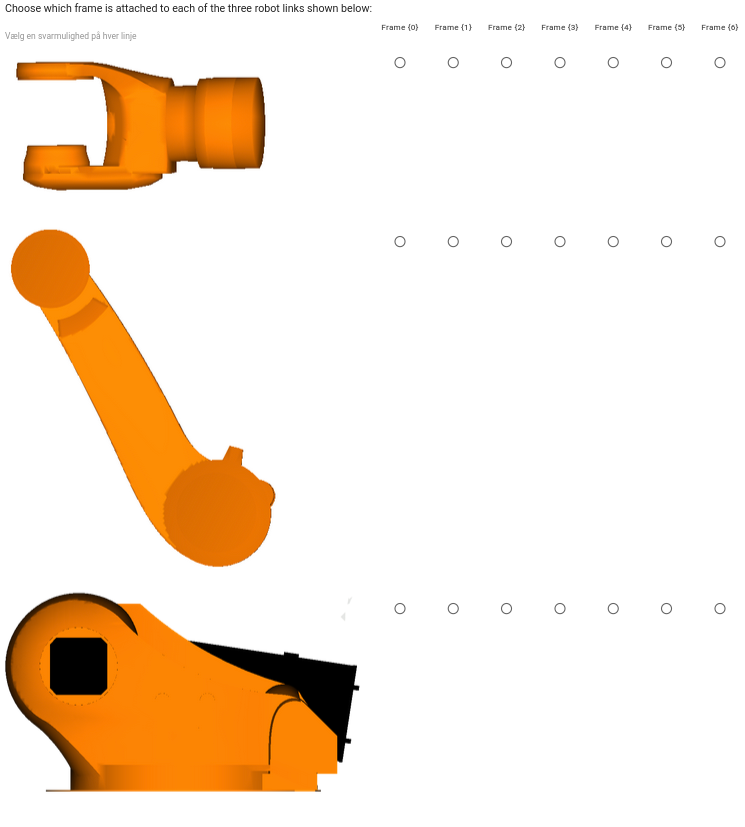

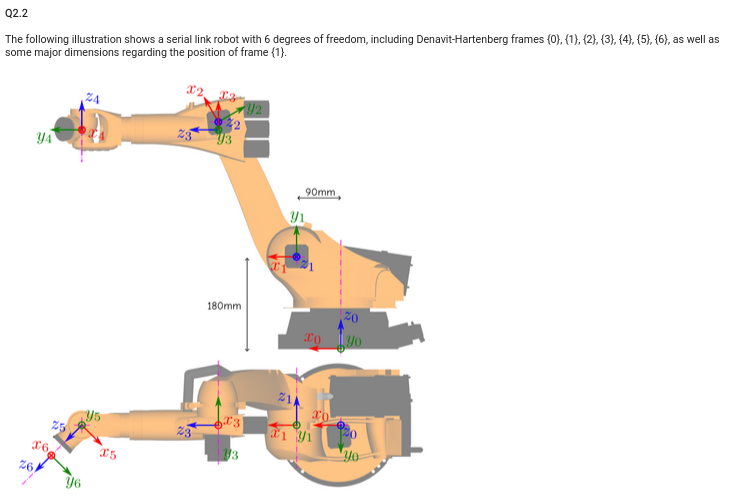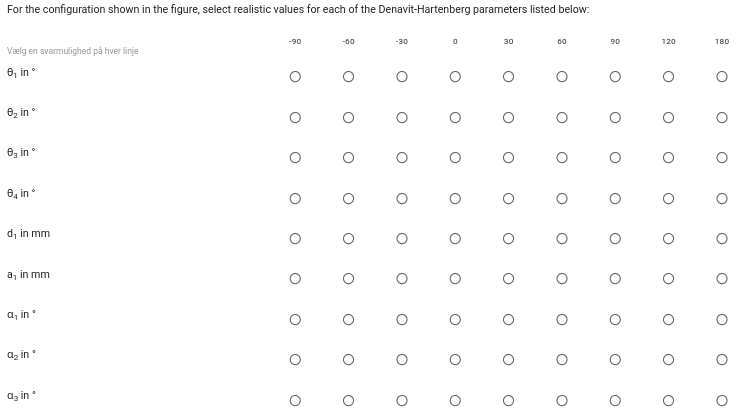

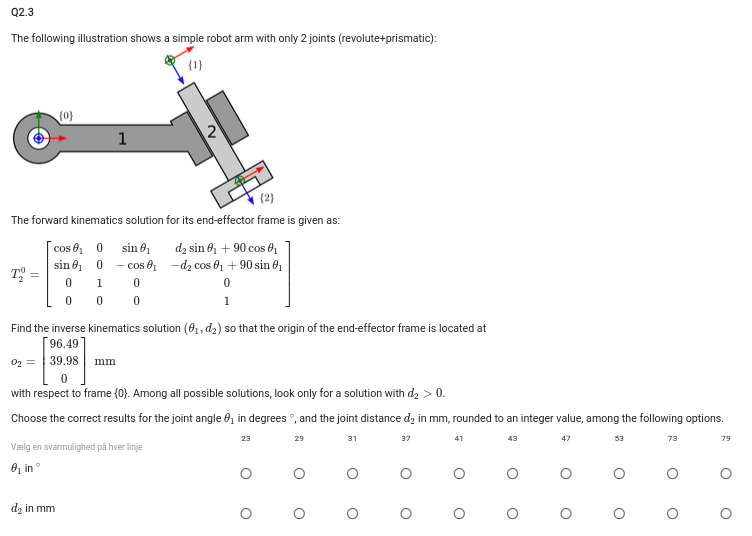

syms T02(theta,d)
T02(theta,d) = [cos(theta) 0 sin(theta) d*sin(theta)+90*cos(theta); sin(theta) 0 -cos(theta) -d*cos(theta)+90*sin(theta);0 1 0 0; 0 0 0 1]

$$T02(theta, d) = \left(\begin{array}{cccc} \cos\left(\theta \right) & 0 & \sin\left(\theta \right) & 90\,\cos\left(\theta \right)+d\,\sin\left(\theta \right)\\ \sin\left(\theta \right) & 0 & -\cos\left(\theta \right) & 90\,\sin\left(\theta \right)-d\,\cos\left(\theta \right)\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


d = [23,29,31,37,41,43,47,53,73,79];
theta = deg2rad(d);

%for k=1:10
%    for j=1:10
%        disp(k)
%        disp(j)
%        T = T02(theta(k),d(j));
%        eval(T)
%    end
%end

eval(T02(theta(8),d(8)))

ans =     0.6018         0    0.7986   96.4910
    0.7986         0   -0.6018   39.9810
         0    1.0000         0         0
         0         0         0    1.0000


# Problem 3

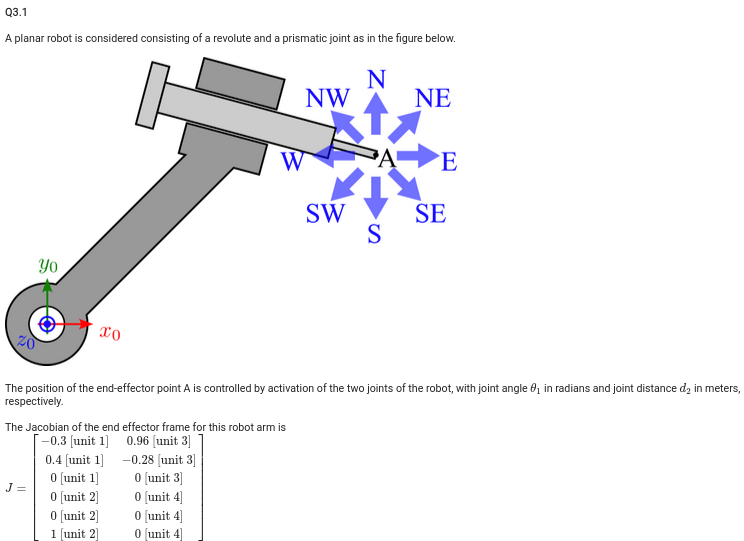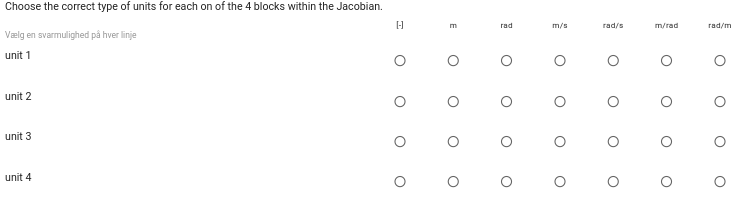

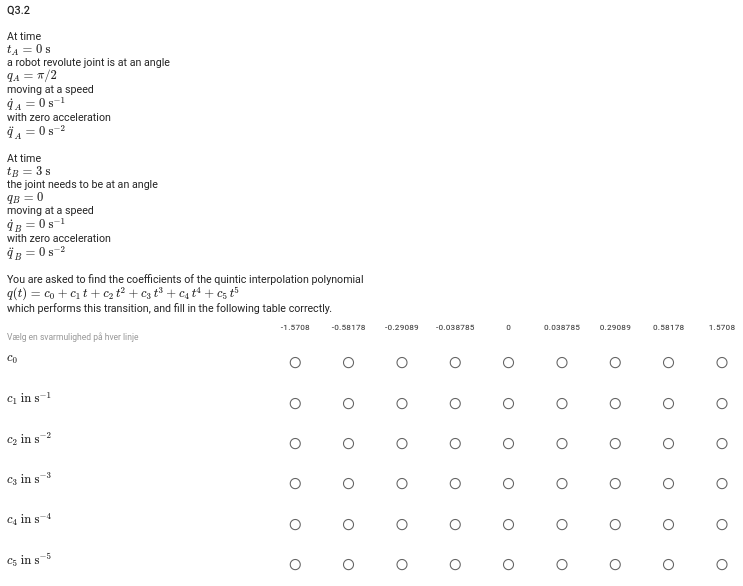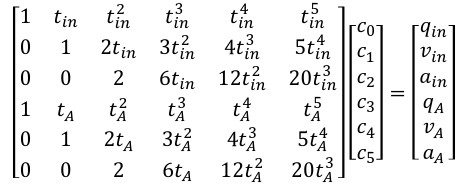

syms c0 c1 c2 c3 c4 c5 
tin = 0;
tb = 3;
c = [c0;c1;c2;c3;c4;c5];
j = [pi/2;0;0;0;0;0];
quin = [1 tin tin^2 tin^3 tin^4 tin^5; 0 1 2*tin 3*tin^2 4*tin^3 5*tin^4; 0 0 2 6*tin 12*tin^2 20*tin^3; 1 tb tb^2 tb^3 tb^4 tb^5; 0 1 2*tb 3*tb^2 4*tb^3 5*tb^4; 0 0 2 6*tb 12*tb^2 20*tb^3];
[c0,c1,c2,c3,c4,c5] = solve(quin*c==j,[c0,c1,c2,c3,c4,c5]);
eval([c0,c1,c2,c3,c4,c5])

ans =     1.5708         0         0   -0.5818    0.2909   -0.0388


# Problem 4

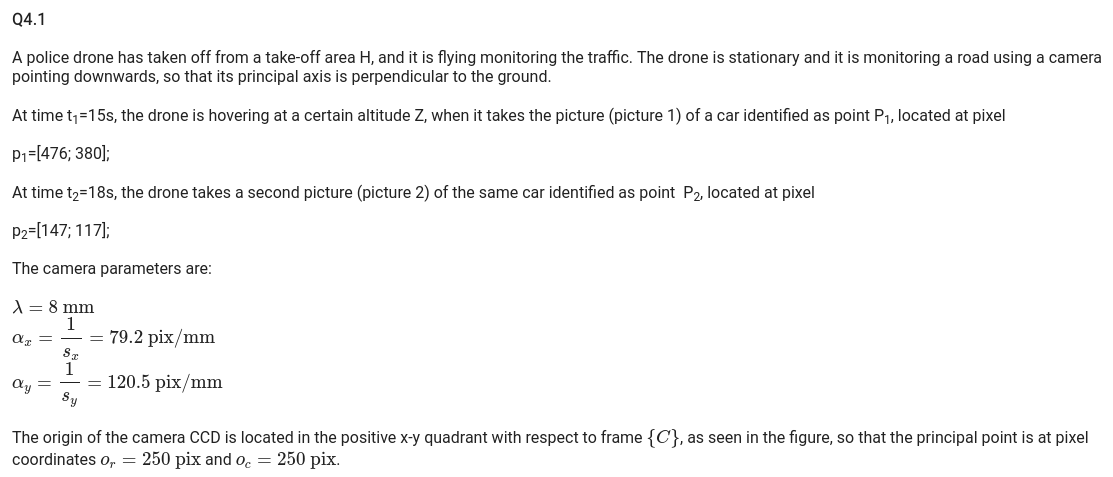

function projections = project_points(points, f, alpha_x, alpha_y, o_r, o_c, p)
    % Project 3D points onto a 2D plane (CCD) using camera parameters.
    %
    % Args:
    % - points: A Nx3 matrix of 3D points in the form [X1, Y1, Z1; X2, Y2, Z2; ...].
    % - f: Focal length in mm.
    % - alpha_x: Pixel scale in x direction (pixels per mm).
    % - alpha_y: Pixel scale in y direction (pixels per mm).
    % - o_r: Image center in the row (u) direction.
    % - o_c: Image center in the column (v) direction.
    % - p: Print the projected points with a label (true or false).
    %
    % Returns:
    % - projections: A Nx2 matrix of projected 2D points on the CCD in pixel coordinates.
    
    % Initialize projections array
    projections = zeros(size(points, 1), 2);
    
    for i = 1:size(points, 1)
        X = points(i, 1);
        Y = points(i, 2);
        Z = points(i, 3);
        
        % Calculate the projection onto the CCD
        u = -f * (X / Z) * alpha_x + o_r;
        v = -f * (Y / Z) * alpha_y + o_c;
        
        % Store the projected point (u, v)
        projections(i, :) = [u, v];
    end
    
    % Round the projections to 2 decimal places
    projections = round(projections, 2);
    
    if p
        % Print each projected point with a label
        for i = 1:size(projections, 1)
            fprintf('P%d = [%0.2f, %0.2f]\n', i, projections(i, 1), projections(i, 2));
        end
    end
end

function d = calculate_distance(f, alpha_x, alpha_y, o_r, o_c, real_dist, p1, p2)
    % Calculate the distance using given camera parameters and points.
    %
    % Args:
    % - f: Focal length in mm.
    % - alpha_x: Pixel scale in x direction (pixels per mm).
    % - alpha_y: Pixel scale in y direction (pixels per mm).
    % - o_r: Image center in the row (u) direction.
    % - o_c: Image center in the column (v) direction.
    % - real_dist: Real distance between points in mm.
    % - p1: First point in pixel coordinates (1x2 vector).
    % - p2: Second point in pixel coordinates (1x2 vector).
    %
    % Returns:
    % - d: Calculated distance.

    % Convert pixel coordinates to real-world coordinates
    p1_real = [p1(1) / alpha_x, p1(2) / alpha_y];
    p2_real = [p2(1) / alpha_x, p2(2) / alpha_y];
    
    % Calculate the pixel distance between the two points
    pixel_dist = sqrt((p1_real(1) - p2_real(1))^2 + (p1_real(2) - p2_real(2))^2);
    
    % Calculate the distance
    d = (f * real_dist) / pixel_dist;
end

p1 = [476,380];
p2 = [147,117];
f = 8;
ax = 79.2; ay = 120.5;
or = 250; oc = 250;

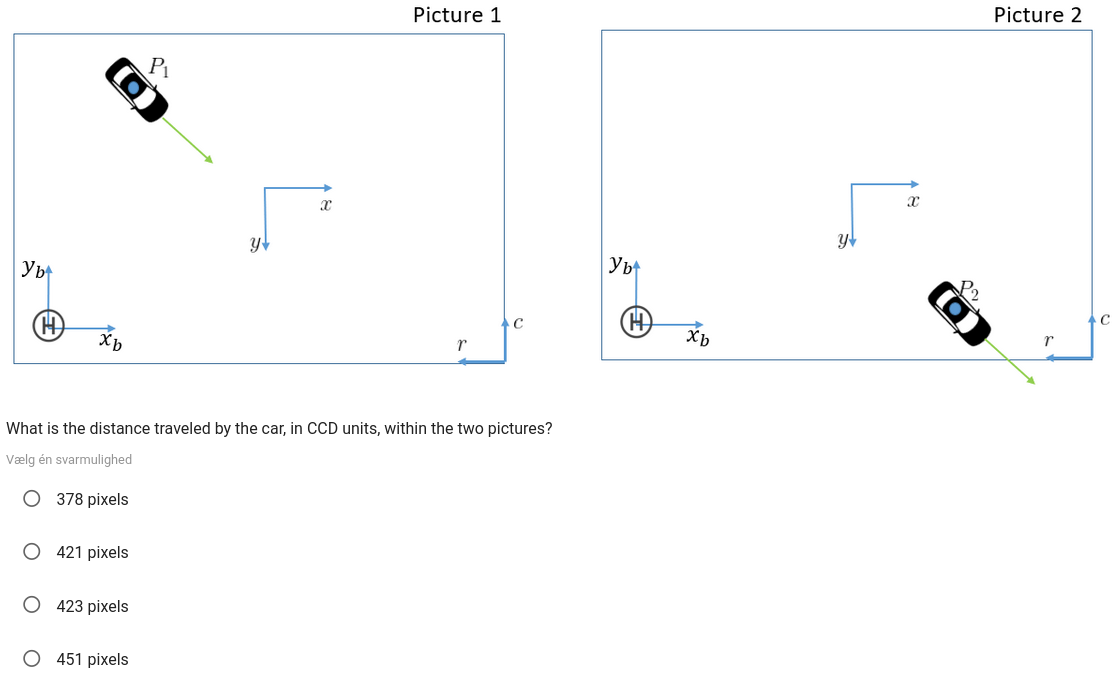

dist_p = [p1(1)-p2(1),p1(2)-p2(2)];
sqrt(dist_p(1)^2+dist_p(2)^2)

ans = 421.2007

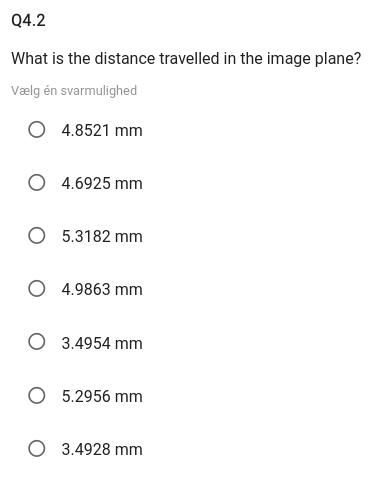

dist_m = [dist_p(1)/ax,dist_p(2)/ay];
sqrt(dist_m(1)^2+dist_m(2)^2)

ans = 4.6925

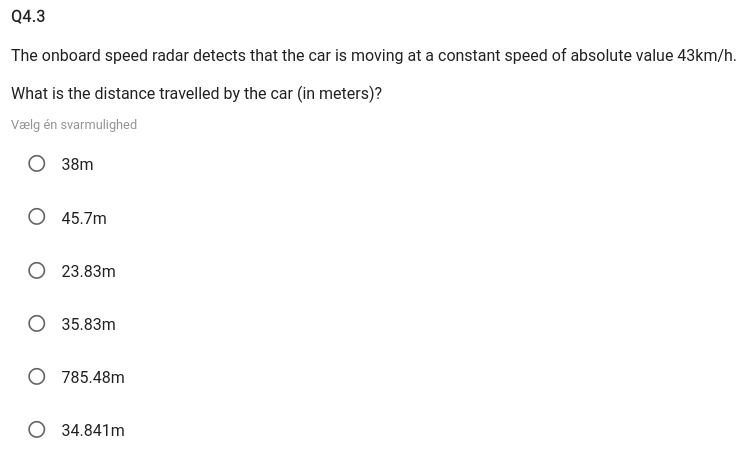

t1 = 15/60/60; t2 = 18/60/60;
(t2-t1)*43*1000

ans = 35.8333

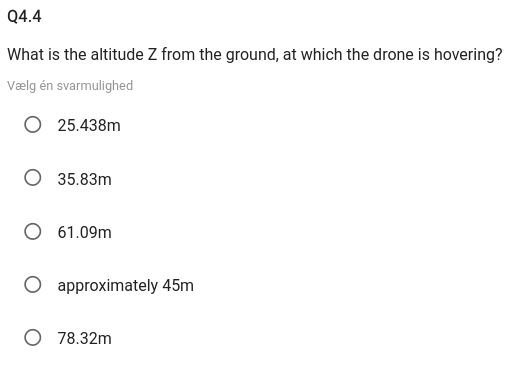

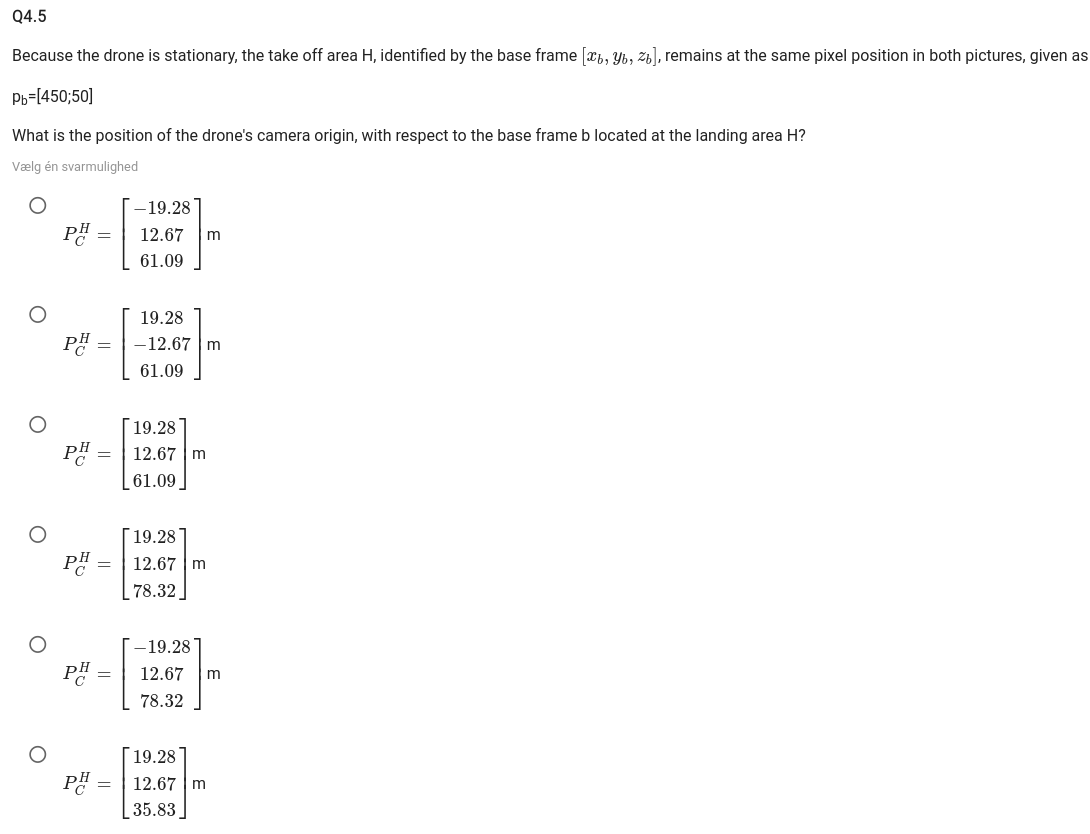

calculate_distance(f, ax, ay, or, oc, [450,50], p1, p2)

ans =   767.1796   85.2422


# Problem 5

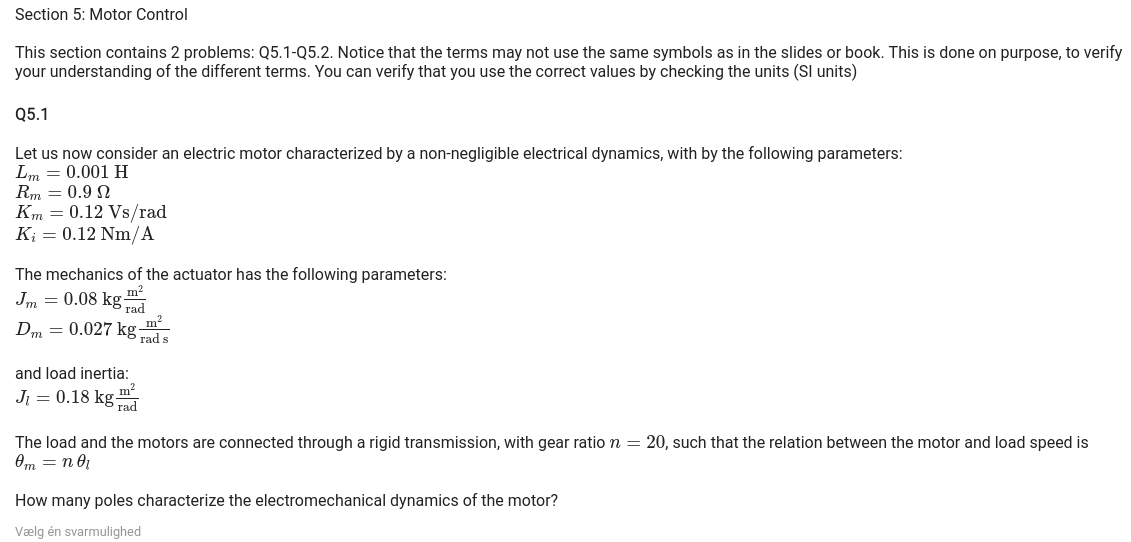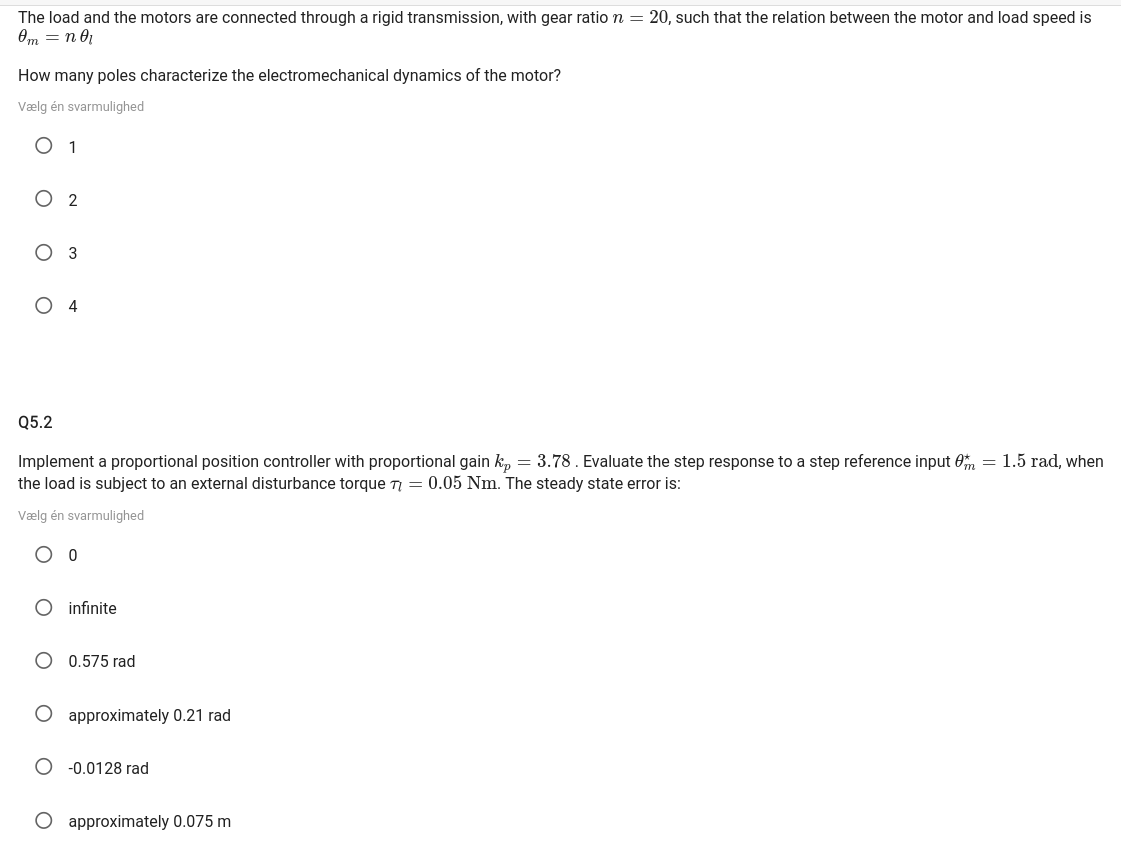

Lm = 0.001; Rm = 0.9; Km = 0.12; Ki = 0.12;
Jm = 0.08; Dm = 0.027; Jl = 0.18; 
syms s
Km/((Jl*s^2+bs)*(Rm+Lm*s)+Km*Ki*s)

Unrecognized function or variable 'bs'.